clear all;

1) 

Wyznaczyć minimum funkcji na kierunku danym przez wektory zawierające wersory bazy.

x1(1)=0.25; x1(2)=-0.1;
x2(1)=0.5; x2(2)=-0.1;



dla punktu startowego  

x0 =[x1(1), x2(1)]

x0 =     0.2500    0.5000


f=@(x1,x2)2.5*(x1.^2-x2).^2+(1-x1).^2 

f = function_handle with value:
    @(x1,x2)2.5*(x1.^2-x2).^2+(1-x1).^2


Wskazówka, wykorzystać funkcję "fminsearch" z Optimization Toolbox - MATLAB.

a = (0.6/0.35);
b = -0.1 + 0.1*a;
prosta = @(x1) (a*x1 + b);
f_pack = @(x) f(x(1), prosta(x(1)));


min_x1 = fminsearch(f_pack, 0);

min_val1 = f_pack(min_x1);

fprintf('Minimum w kierunku v2: x = %f, y = %f, wartość funkcji = %f\n', min_x1, prosta(min_x1), min_val1);

Minimum w kierunku v2: x = 0.103313, y = 0.248536, wartość funkcji = 0.945495


2)

Wyznaczyć punkty funkcji metodami minimalizacji na kierunku: 

a) punkty zerowe funkcji

b) punkty dla których funkcja przyjmuje wartość =1

f= @(x) x.^2 +2.*x- 5

f = function_handle with value:
    @(x)x.^2+2.*x-5


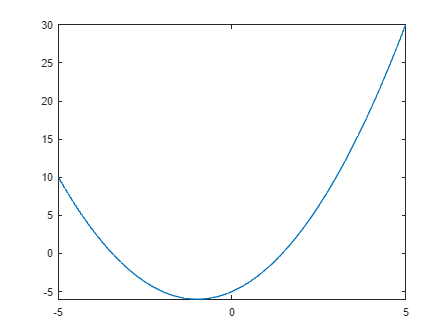

fplot(f)

Wskazówka, wykorzystać funkcję "fminsearch" z Optimization Toolbox - MATLAB.

x0 = 0;

f_pack = @(x) (f(x).^2);

fplot(f_pack)

[minimum_x] = fminsearch(f_pack, x0) %zero

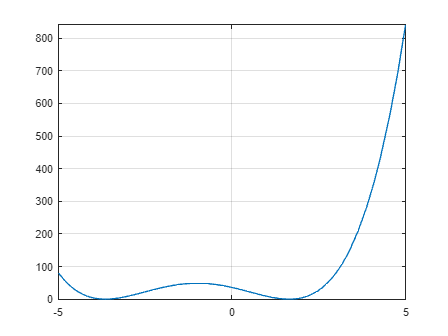

f_pack = @(x) (f(x)-1).^2;
fplot(f_pack)
grid on;

x0 = -4;
[minimum_x] = fminsearch(f_pack, x0) %jeden

minimum_x = -3.6457

x0 = 2.7;
[minimum_x] = fminsearch(f_pack, x0) %jeden

minimum_x = 1.6458

3)

Dany jest system dynamiczny opisany transmitancją G1

global G1;
global t;
s = tf([1 0], [0 1]);

G1=tf([0 1],[1 2 2.25 1.25]);
[G1p_Licz,G1p_Mian]=pade(0.5,3);
G1p=tf(G1p_Licz,G1p_Mian);
G1=G1*G1p

G1 =
 
                   -s^3 + 24 s^2 - 240 s + 960
  --------------------------------------------------------------
  s^6 + 26 s^5 + 290.2 s^4 + 1495 s^3 + 2490 s^2 + 2460 s + 1200
 
Continuous-time transfer function.



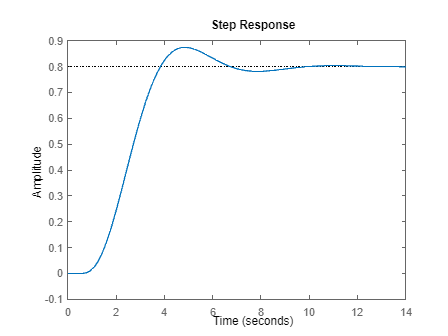

step(G1)


[y, t] = step(G1, t);
k = y(end)

k = 0.8006


t = linspace(0, 15, 5000);

param0 = 6;

out_par = fminsearch(@f_obj, param0)

out_par = 2.4240

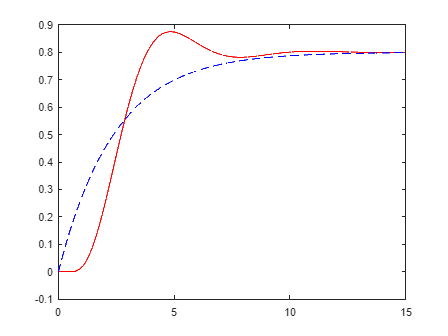


G_approx = tf([0, 0.8], [out_par, 1]);


plot(t, step(G1, t), '-r', t, step(G_approx, t), '--b')

Wykorzystując metody minimalizacji na **kierunku** wykonać optymalizację systemu dynamicznego **pierwszego rzędu opisanego transmitancją G2**, który będzie estymował (optymalnie przybliżał) system opisany transmitancją G1.

Wskazówka, wykorzystać funkcję "fminsearch" z Optimization Toolbox - MATLAB.

function [val] = f_obj(param)

global t;
global G1;

loc_t = t;

G_test = tf([0, 0.8], [param, 1]);
%G_test = G_test * pade(param(3), 3)

% Calculate the step response of G1 and G_test
step_response_G1 = step(G1, t);
step_response_G_test = step(G_test, t);

% Calculate the RMS error point-wise
error = step_response_G1 - step_response_G_test;
rms_error = sqrt(mean(error.^2));

val = rms_error;
end